# Test met functies


toy_samples = 250;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(1,i), Jac(1,:,i)] = dlfeval(@f1, point);
    [F(2,i), Jac(2,:,i)] = dlfeval(@f2, point);
end

## Test met neuraal netwerk [ 2 2 3 2 2]


toy_samples = 200;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(:,i), Jac(:,:,i)] = dlfeval(@all_layers, point);
end

## Test met neuraal netwerk [ 3 5 4 3 2]


toy_samples = 200;
nb_inputs = 3;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(:,i), Jac(:,:,i)] = dlfeval(@all_layers2, point);
end

## Test met MNIST

data = load('mnist_train.csv');
%data = load('mnist1d_train.csv');
images = data(:,2:size(data,2));
% Only for MNIST dataset (not MNIST-1D)
images = images/255;
images = images';

toy_samples = 360;
nb_inputs = 784;
nb_outputs = 40;

sampling_indexes = randi([1 size(images,2)], toy_samples, 1);
sampling_points = zeros(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);

we12 = matfile('MNIST/3_layer/parameters/wtwo.mat');
%we12 = matfile('MNIST/3_layer/final_parameters/wtwo.mat');
w2 = we12.w12;

bi12 = matfile('MNIST/3_layer/parameters/btwo.mat');
%bi12 = matfile('MNIST/3_layer/final_parameters/btwo.mat');
b2 = bi12.b12;

for i=1:toy_samples
    point = dlarray(images(:,sampling_indexes(i)));
    
    input = point;
    %input = dlarray(elu(dlarray(w2*point + b2)));

    sampling_points(:,i) = input;
    [F(:,i), Jac(:,:,i)] = dlfeval(@three_layers_MNIST, input);
end

## Algoritme oproep zonder regularisatie

warning("off")

bf1 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta6, @theta7};
bf2 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta6, @theta7};

r1 = 30;
r2 = 30;

[We, D2e, Vte, D1e, Zte, Ht, cD1e, cD2e] = PARATUCK2_CMTF(Jac, F, bf1, bf2, r1, r2, sampling_points);

## Algoritme oproep met regularisatie

warning("off")

bf1 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta6, @theta7, @theta8, @theta9, @theta10};
bf1d = {@theta1d, @theta2d, @theta3d, @theta4d, @theta5d};
bf2 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta6, @theta7, @theta8, @theta9, @theta10};
bf2d = {@theta1d, @theta2d, @theta3d, @theta4d, @theta5d};%, @theta6, @theta7, @theta8, @theta9, @theta10};

r1 = 35;
r2 = 40;

tic
[We, D2e, Vte, D1e, Zte, Ht, cD1e, cD2e] = PARATUCK2_CMTF_REG(Jac, F, bf1, bf1d, bf2, bf2d, r1, r2, sampling_points);

i = 1

Jerror = 0.7454

Ferror = 0.6693

i = 2

Jerror = 0.5095

Ferror = 0.1894

i = 3

Jerror = 0.4314

Ferror = 0.1944

i = 4

Jerror = 0.4034

Ferror = 63.0225

i = 5

Jerror = 0.3843

Ferror = 7.4368

i = 6

Jerror = 0.3743

Ferror = 45.6502

i = 7

Jerror = 0.3687

Ferror = 41.6450

i = 8

Jerror = 0.3647

Ferror = 24.3042

i = 9

Jerror = 0.3625

Ferror = 13.1118

i = 10

Jerror = 0.3606

Ferror = 16.2355

i = 11

Jerror = 0.3589

Ferror = 2.0304

i = 12

Jerror = 0.3575

Ferror = 1.7895

i = 13

Jerror = 0.3564

Ferror = 1.4243

i = 14

Jerror = 0.3550

Ferror = 1.0145

i = 15

Jerror = 0.3538

Ferror = 1.3050

i = 16

Jerror = 0.3530

Ferror = 1.4069

i = 17

Jerror = 0.3528

Ferror = 1.0751

toc

## Vergelijking met functies

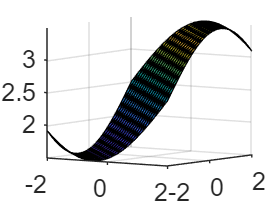

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,nb_outputs);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], We, Vte, Zte, cD1e, cD2e, r1, r2);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)
view([35.05 6.20])

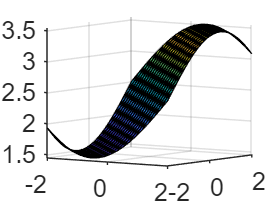

% Benadering
surf(x,y,zb(:,:,1))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([1.45 3.55])

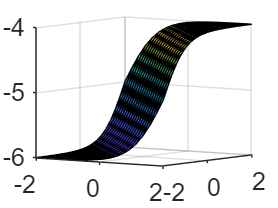



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)

view([35.05 6.20])

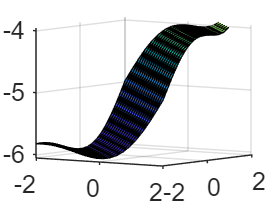

% Benadering
surf(x,y,zb(:,:,2))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([-6.05 -3.95])

## Vergelijking met netwerk 1

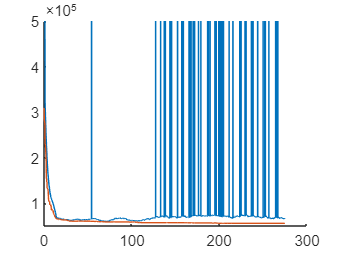

u = dlarray([0.1 0.3])
[result, ~] = dlfeval(@all_layers, u);
result

apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult


u = dlarray([0.5 0.5])
[result, ~] = dlfeval(@all_layers, u);
result

apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult


u = dlarray([0.2 0.2])
[result, ~] = dlfeval(@all_layers, u);
result

apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

## Vergelijking met netwerk 2

u = dlarray([0.1 0.3 0.1])

u =   1×3 dlarray

    0.1000    0.3000    0.1000


[result, ~] = dlfeval(@all_layers2, u);
result

result =    -0.2424
    1.2598



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.2422
    1.2594




u = dlarray([0.5 0.5 0.5])

u =   1×3 dlarray

    0.5000    0.5000    0.5000


[result, ~] = dlfeval(@all_layers2, u);
result

result =    -0.2437
    1.2629



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.2433
    1.2622




u = dlarray([0.2 0.2 0.4])

u =   1×3 dlarray

    0.2000    0.2000    0.4000


[result, ~] = dlfeval(@all_layers2, u);
result

result =    -0.2433
    1.2619


apprResult =    -0.2430
    1.2615


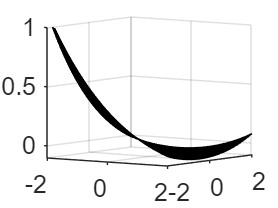

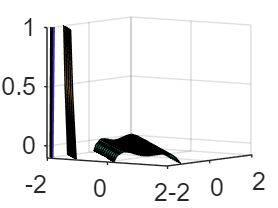

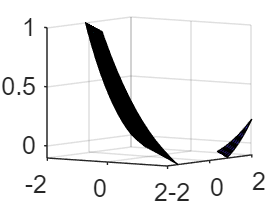

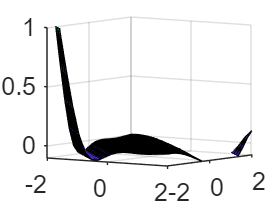


apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

## Compression rate berekenen

compressed = [784 60 50 10];
not_compr = [784 80 60 40 10];

compression = compression_rate(compressed, not_compr, 60, 50)

compression = 0.3983

## Resultaten opslaan

save("SavedVariables/PARATUCK2/Structured/CMTF/MNIST/CPD_network_784_80_60_40_10__784_80_21_10_S360_1");

save("SavedVariables/PARATUCK2/Structured/CMTF/PT2_REG_toy_network2_3_2_S200_2");

function [f,grad] = f1(x)
    f = 2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f2(x)
    f = -5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

function [f,grad] = f3(x)
    f = cos(sum(x)) - 1;
    grad = dlgradient(f,x);
end

function[f,grad] = all_layers(x)
    W0 = [0.2, 0.4; 0.5, 0.1];
    W1 = [0.02, 0.3; 0.1, 0.4; 0.2, 0.6];
    W3 = [0.4 0.3 0.3; 0.1 0.5 0.2];
    W4 = [-0.7 0.3; 0.5, 1.3];

    interm1 = arrayfun(@sigmoid, W0*x');
    interm2 = arrayfun(@sigmoid, W1 * interm1);
    interm4 = arrayfun(@sigmoid, W3 * interm2);


    f1 = W4(1,:)*interm4;
    f2 = W4(2,:)*interm4;

    f = zeros(2,1);
    f(1) = f1;
    f(2) = f2;
    %f(3) = f3;
    %f(4) = f4;

    grad1 = dlgradient(f1,x);
    grad2 = dlgradient(f2,x);
    %grad3 = dlgradient(f3,x);
    %grad4 = dlgradient(f4,x);

    grad = zeros(2,2);
    grad(1,:) = grad1;
    grad(2,:) = grad2;
    %grad(3,:) = grad3;
    %grad(4,:) = grad4;
end

function[f,grad] = all_layers2(x)
    W0 = [0.2, 0.4, 0.4; 
        0.5, 0.1, 0.3; 
        -0.1, 0.1, 0.1; 
        0.8, -0.2, 0.4;
        0.2, -0.8, 0.1];
    W1 = [0.02, 0.3, 0.2, -0.3, 0.1;
        -0.1, 0.4, 0.6, 0.2, 0;
        0.2, 0.6, 0.4, 0.4, 0.4;
        -0.5, 0.1, .03, 0.7, 0.4];
    W3 = [0.4 0.3 0.3, 0.4;
        0.1 0.5 -0.2, 0.2;
        0.4 0.3 0.4 0.6];
    W4 = [-0.7 0.3 0.1; 0.5, 1.3 0.2];

    interm1 = arrayfun(@sigmoid, W0*x');
    interm2 = arrayfun(@sigmoid, W1 * interm1);
    interm4 = arrayfun(@sigmoid, W3 * interm2);


    f1 = W4(1,:)*interm4;
    f2 = W4(2,:)*interm4;

    f = zeros(2,1);
    f(1) = f1;
    f(2) = f2;
    %f(3) = f3;
    %f(4) = f4;

    grad1 = dlgradient(f1,x);
    grad2 = dlgradient(f2,x);
    %grad3 = dlgradient(f3,x);
    %grad4 = dlgradient(f4,x);

    grad = zeros(2,3);
    grad(1,:) = grad1;
    grad(2,:) = grad2;
    %grad(3,:) = grad3;
    %grad(4,:) = grad4;
end

function fr = elu(x)
    f = dlarray(zeros(length(x),1));
    for i = 1:length(x)
        if x(i)>=0
            f(i) = x(i);
        else
            f(i) = 0.2*(exp(x(i))-1);
        end
    end
    fr = f;
end

function[f,grad] = three_layers_MNIST(x)
    
    we45 = matfile('MNIST/3_layer/parameters/wfive.mat');
    %we45 = matfile('MNIST/3_layer/final_parameters/wfive.mat');
    w5 = we45.w45;
    we34 = matfile('MNIST/3_layer/parameters/wfour.mat');
    %we34 = matfile('MNIST/3_layer/final_parameters/wfour.mat');
    w4 = we34.w34;
    we23 = matfile('MNIST/3_layer/parameters/wthree.mat');
    %we23 = matfile('MNIST/3_layer/final_parameters/wthree.mat');
    w3 = we23.w23;
    we12 = matfile('MNIST/3_layer/parameters/wtwo.mat');
    %we23 = matfile('MNIST/3_layer/final_parameters/wtwo.mat');
    w2 = we12.w12;
    
    bi45 = matfile('MNIST/3_layer/parameters/bfive.mat');
    %bi45 = matfile('MNIST/3_layer/final_parameters/bfive.mat');
    b5 = bi45.b45;
    bi34 = matfile('MNIST/3_layer/parameters/bfour.mat');
    %bi34 = matfile('MNIST/3_layer/final_parameters/bfour.mat');
    b4 = bi34.b34;
    bi23 = matfile('MNIST/3_layer/parameters/bthree.mat');
    %bi23 = matfile('MNIST/3_layer/final_parameters/bthree.mat');
    b3 = bi23.b23;
    bi12 = matfile('MNIST/3_layer/parameters/btwo.mat');
    %bi23 = matfile('MNIST/3_layer/final_parameters/btwo.mat');
    b2 = bi12.b12;
    
    interm0 = elu(dlarray(w2*x + b2));
    interm1 = elu(dlarray(w3*interm0 + b3));
    %interm1 = elu(dlarray(w3*x + b3));
    %interm2 = elu(dlarray(w4 * interm1 + b4));
    f = dlarray(w4 * interm1 + b4);
    %f = elu(dlarray(w5 * interm2 + b5));
    %f = dlarray(w5 * interm2 + b5);


%     f1 = f(1);
%     f2 = f(2);
%     f3 = f(3);
%     f4 = f(4);
%     f5 = f(5);
%     f6 = f(6);
%     f7 = f(7);
%     f8 = f(8);
%     f9 = f(9);
%     f10 = f(10);

%     grad1 = dlgradient(f1,x);
%     grad2 = dlgradient(f2,x);
%     grad3 = dlgradient(f3,x);
%     grad4 = dlgradient(f4,x);
%     grad5 = dlgradient(f5,x);
%     grad6 = dlgradient(f6,x);
%     grad7 = dlgradient(f7,x);
%     grad8 = dlgradient(f8,x);
%     grad9 = dlgradient(f9,x);
%     grad10 = dlgradient(f10,x);

    
    outputs = 40;
    grad = zeros(outputs,size(w2,2));
    for i=1:outputs
        grad(i,:) = dlgradient(f(i),x);
    end
    %grad = zeros(10,size(w3,2));
%     grad(1,:) = grad1;
%     grad(2,:) = grad2;
%     grad(3,:) = grad3;
%     grad(4,:) = grad4;
%     grad(5,:) = grad5;
%     grad(6,:) = grad6;
%     grad(7,:) = grad7;
%     grad(8,:) = grad8;
%     grad(9,:) = grad9;
%     grad(10,:) = grad10;
end


function [f] = fbar(input, W, Vt, Zt, cD1, cD2, r1, r2)
    P1 = zeros(r1,1);
    x = Zt * input;
    for i=1:r1
        P1(i,1) = cD1((7* (i - 1)) + 1) * x(i) + ...
                 cD1((7* (i - 1)) + 2) * x(i)^2 + ...
                 cD1((7* (i - 1)) + 3) * x(i)^3 + ...
                 cD1((7* (i - 1)) + 4) * x(i)^4 + ...
                 cD1((7* (i - 1)) + 5) * x(i)^5 + ...
                 cD1((7* (i - 1)) + 6) * x(i)^6 + ...
                 cD1((7* (i - 1)) + 7) * x(i)^7;
    end

    P2 = zeros(r2,1);
    x = Vt * P1;
    for i=1:r2
        P2(i,1) = cD2((8* (i - 1)) + 1) + ...
                 cD2((8* (i - 1)) + 2) * x(i) + ...
                 cD2((8* (i - 1)) + 3) * x(i)^2 + ...
                 cD2((8* (i - 1)) + 4) * x(i)^3 + ...
                 cD2((8* (i - 1)) + 5) * x(i)^4 + ...
                 cD2((8* (i - 1)) + 6) * x(i)^5 + ...
                 cD2((8* (i - 1)) + 7) * x(i)^6 + ...
                 cD2((8* (i - 1)) + 8) * x(i)^7;
    end

    f = W * P2;
end


% function [f,grad] = theta1(x)
%     f = x;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta2(x)
%     f = x^2;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta3(x)
%     f = x^3;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta4(x)
%     f = x^4;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta5(x)
%     f = x^5;
%     grad = dlgradient(f,x);
% end

function [f] = theta1(x)
    f = x;
end

function [f] = theta1d(x)
    f = 1;
end

function [f] = theta2(x)
    f = x^2;
end

function [f] = theta2d(x)
    f = 2*x;
end

function [f] = theta3(x)
    f = x^3;
end

function [f] = theta3d(x)
    f = 3*x^2;
end

function [f] = theta4(x)
    f = x^4;
end

function [f] = theta4d(x)
    f = 4*x^3;
end

function [f] = theta5(x)
    f = x^5;
end

function [f] = theta5d(x)
    f = 5*x^4;
end

function [f,grad] = theta6(x)
    f = x^6;
    grad = dlgradient(f,x);
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end

function [rate] = compression_rate(nodes1, nodes2, d1, d2)
    rate1 = 0;
    for i=1:size(nodes1,2)-1
        rate1 = rate1 + nodes1(i) * nodes1(i+1);
    end
    rate1 = rate1 + d1 + d2 + 2;

    rate2 = 0;
    for i=1:size(nodes2,2)-1
        rate2 = rate2 + nodes2(i) * nodes2(i+1);
    end

    rate = 1 - rate1 / rate2;
end
